## Trajectory calculation

This is where we will calculate our desired trajectories for each joint. For this we will be using a 5th degree polynomial.

% desired time and the number of samples our time should be split into
T = 10

T = 10

n = 100

n = 100

timp=linspace(0,T,n)

timp =          0    0.1010    0.2020    0.3030    0.4040    0.5051    0.6061    0.7071    0.8081    0.9091    1.0101    1.1111    1.2121    1.3131    1.4141    1.5152    1.6162    1.7172    1.8182    1.9192    2.0202    2.1212    2.2222    2.3232    2.4242    2.5253    2.6263    2.7273    2.8283    2.9293    3.0303    3.1313    3.2323    3.3333    3.4343    3.5354    3.6364    3.7374    3.8384    3.9394    4.0404    4.1414    4.2424    4.3434    4.4444    4.5455    4.6465    4.7475    4.8485    4.9495


% first joint
p1 = trajectory(pi/2, T)

p1 =     0.0001   -0.0024    0.0157         0         0         0


dp1 = polyder(p1)

dp1 =     0.0005   -0.0094    0.0471         0         0


ddp1 = polyder(dp1)

ddp1 =     0.0019   -0.0283    0.0942         0



% angle, angular velocity and angular acceleration
% these describe the trajectory our robot arm should follow
q1=polyval(p1,timp)

q1 =          0    0.0000    0.0001    0.0004    0.0010    0.0019    0.0032    0.0050    0.0073    0.0103    0.0138    0.0181    0.0231    0.0289    0.0355    0.0430    0.0513    0.0605    0.0705    0.0815    0.0934    0.1063    0.1200    0.1347    0.1503    0.1668    0.1842    0.2025    0.2217    0.2417    0.2625    0.2841    0.3065    0.3297    0.3535    0.3781    0.4032    0.4290    0.4554    0.4823    0.5096    0.5375    0.5657    0.5942    0.6231    0.6523    0.6816    0.7111    0.7408    0.7705


save q1.mat q1
dq1=polyval(dp1,timp)

dq1 =          0    0.0005    0.0018    0.0041    0.0071    0.0108    0.0153    0.0203    0.0260    0.0322    0.0389    0.0460    0.0535    0.0613    0.0695    0.0779    0.0865    0.0953    0.1043    0.1133    0.1225    0.1316    0.1408    0.1499    0.1589    0.1679    0.1767    0.1854    0.1939    0.2022    0.2102    0.2180    0.2255    0.2327    0.2396    0.2461    0.2523    0.2582    0.2636    0.2686    0.2732    0.2774    0.2812    0.2845    0.2873    0.2897    0.2916    0.2930    0.2940    0.2945


save dq1.mat dq1
ddq1=polyval(ddp1,timp)

ddq1 =          0    0.0092    0.0179    0.0260    0.0336    0.0406    0.0472    0.0532    0.0587    0.0637    0.0683    0.0724    0.0761    0.0793    0.0821    0.0844    0.0864    0.0880    0.0892    0.0901    0.0905    0.0907    0.0905    0.0900    0.0892    0.0881    0.0866    0.0850    0.0830    0.0808    0.0784    0.0758    0.0729    0.0698    0.0665    0.0631    0.0595    0.0557    0.0518    0.0477    0.0436    0.0393    0.0349    0.0304    0.0259    0.0212    0.0166    0.0119    0.0071    0.0024


save ddq1.mat ddq1

% save them as .mat for easy simulink access
q1time = timeseries(q1, timp)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [100x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x100 double]
        DataInfo: 

save q1time.mat q1time
dq1time = timeseries(dq1, timp)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [100x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x100 double]
        DataInfo: 

save dq1time.mat dq1time
ddq1time = timeseries(ddq1, timp)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [100x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x100 double]
        DataInfo: 

save ddq1time.mat ddq1time

% second joint
p2 = trajectory(pi/2, T)

p2 =     0.0001   -0.0024    0.0157         0         0         0


dp2 = polyder(p2)

dp2 =     0.0005   -0.0094    0.0471         0         0


ddp2 = polyder(dp2)

ddp2 =     0.0019   -0.0283    0.0942         0



% angle, angular velocity and angular acceleration
% these describe the trajectory our robot arm should follow
q2=polyval(p2,timp)

q2 =          0    0.0000    0.0001    0.0004    0.0010    0.0019    0.0032    0.0050    0.0073    0.0103    0.0138    0.0181    0.0231    0.0289    0.0355    0.0430    0.0513    0.0605    0.0705    0.0815    0.0934    0.1063    0.1200    0.1347    0.1503    0.1668    0.1842    0.2025    0.2217    0.2417    0.2625    0.2841    0.3065    0.3297    0.3535    0.3781    0.4032    0.4290    0.4554    0.4823    0.5096    0.5375    0.5657    0.5942    0.6231    0.6523    0.6816    0.7111    0.7408    0.7705


save q2.mat q2
dq2=polyval(dp2,timp)

dq2 =          0    0.0005    0.0018    0.0041    0.0071    0.0108    0.0153    0.0203    0.0260    0.0322    0.0389    0.0460    0.0535    0.0613    0.0695    0.0779    0.0865    0.0953    0.1043    0.1133    0.1225    0.1316    0.1408    0.1499    0.1589    0.1679    0.1767    0.1854    0.1939    0.2022    0.2102    0.2180    0.2255    0.2327    0.2396    0.2461    0.2523    0.2582    0.2636    0.2686    0.2732    0.2774    0.2812    0.2845    0.2873    0.2897    0.2916    0.2930    0.2940    0.2945


save dq2.mat dq2
ddq2=polyval(ddp2,timp)

ddq2 =          0    0.0092    0.0179    0.0260    0.0336    0.0406    0.0472    0.0532    0.0587    0.0637    0.0683    0.0724    0.0761    0.0793    0.0821    0.0844    0.0864    0.0880    0.0892    0.0901    0.0905    0.0907    0.0905    0.0900    0.0892    0.0881    0.0866    0.0850    0.0830    0.0808    0.0784    0.0758    0.0729    0.0698    0.0665    0.0631    0.0595    0.0557    0.0518    0.0477    0.0436    0.0393    0.0349    0.0304    0.0259    0.0212    0.0166    0.0119    0.0071    0.0024


save ddq2.mat ddq2

% save them as .mat for easy simulink access
q2time = timeseries(q2, timp)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [100x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x100 double]
        DataInfo: 

save q2time.mat q2time
dq2time = timeseries(dq2, timp)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [100x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x100 double]
        DataInfo: 

save dq2time.mat dq2time
ddq2time = timeseries(ddq2, timp)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [100x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x100 double]
        DataInfo: 

save ddq2time.mat ddq2time

Q_dorit = [q1;
    q2]

Q_dorit =          0    0.0000    0.0001    0.0004    0.0010    0.0019    0.0032    0.0050    0.0073    0.0103    0.0138    0.0181    0.0231    0.0289    0.0355    0.0430    0.0513    0.0605    0.0705    0.0815    0.0934    0.1063    0.1200    0.1347    0.1503    0.1668    0.1842    0.2025    0.2217    0.2417    0.2625    0.2841    0.3065    0.3297    0.3535    0.3781    0.4032    0.4290    0.4554    0.4823    0.5096    0.5375    0.5657    0.5942    0.6231    0.6523    0.6816    0.7111    0.7408    0.7705
         0    0.0000    0.0001    0.0004    0.0010    0.0019    0.0032    0.0050    0.0073    0.0103    0.0138    0.0181    0.0231    0.0289    0.0355    0.0430    0.0513    0.0605    0.0705    0.0815    0.0934    0.1063    0.1200    0.1347    0.1503    0.1668    0.1842    0.2025    0.2217    0.2417    0.2625    0.2841    0.3065    0.3297    0.3535    0.3781    0.4032    0.4290    0.4554    0.4823    0.5096    0.5375    0.5657    0.5942    0.6231    0.6523    0.6816    0.7111    0.740

dQ_dorit = [dq1;
    dq2]

dQ_dorit =          0    0.0005    0.0018    0.0041    0.0071    0.0108    0.0153    0.0203    0.0260    0.0322    0.0389    0.0460    0.0535    0.0613    0.0695    0.0779    0.0865    0.0953    0.1043    0.1133    0.1225    0.1316    0.1408    0.1499    0.1589    0.1679    0.1767    0.1854    0.1939    0.2022    0.2102    0.2180    0.2255    0.2327    0.2396    0.2461    0.2523    0.2582    0.2636    0.2686    0.2732    0.2774    0.2812    0.2845    0.2873    0.2897    0.2916    0.2930    0.2940    0.2945
         0    0.0005    0.0018    0.0041    0.0071    0.0108    0.0153    0.0203    0.0260    0.0322    0.0389    0.0460    0.0535    0.0613    0.0695    0.0779    0.0865    0.0953    0.1043    0.1133    0.1225    0.1316    0.1408    0.1499    0.1589    0.1679    0.1767    0.1854    0.1939    0.2022    0.2102    0.2180    0.2255    0.2327    0.2396    0.2461    0.2523    0.2582    0.2636    0.2686    0.2732    0.2774    0.2812    0.2845    0.2873    0.2897    0.2916    0.2930    0.29

ddQ_dorit = [ddq1;
    ddq2]

ddQ_dorit =          0    0.0092    0.0179    0.0260    0.0336    0.0406    0.0472    0.0532    0.0587    0.0637    0.0683    0.0724    0.0761    0.0793    0.0821    0.0844    0.0864    0.0880    0.0892    0.0901    0.0905    0.0907    0.0905    0.0900    0.0892    0.0881    0.0866    0.0850    0.0830    0.0808    0.0784    0.0758    0.0729    0.0698    0.0665    0.0631    0.0595    0.0557    0.0518    0.0477    0.0436    0.0393    0.0349    0.0304    0.0259    0.0212    0.0166    0.0119    0.0071    0.0024
         0    0.0092    0.0179    0.0260    0.0336    0.0406    0.0472    0.0532    0.0587    0.0637    0.0683    0.0724    0.0761    0.0793    0.0821    0.0844    0.0864    0.0880    0.0892    0.0901    0.0905    0.0907    0.0905    0.0900    0.0892    0.0881    0.0866    0.0850    0.0830    0.0808    0.0784    0.0758    0.0729    0.0698    0.0665    0.0631    0.0595    0.0557    0.0518    0.0477    0.0436    0.0393    0.0349    0.0304    0.0259    0.0212    0.0166    0.0119    0.0

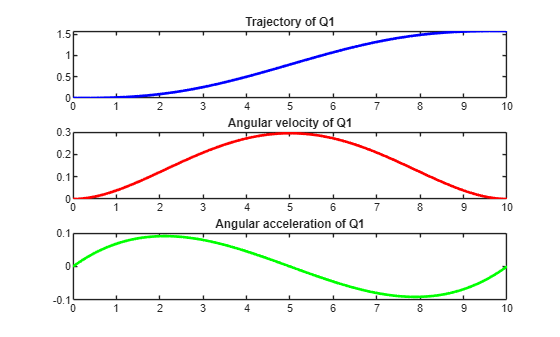

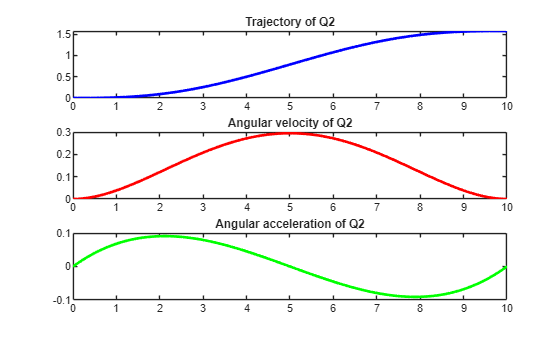

% plots of how our desired trajectories look
for i=1:2
    figure
    subplot(3,1,1)
    plot(timp,Q_dorit(i,:),'b','linewidth',2)
    title(['Trajectory of Q', num2str(i)])
    subplot(3,1,2) 
    plot(timp,dQ_dorit(i,:),'r','linewidth',2)
    title(['Angular velocity of Q', num2str(i)])
    subplot(3,1,3) 
    plot(timp,ddQ_dorit(i,:),'g','linewidth',2)
    title(['Angular acceleration of Q', num2str(i)])
end